# Homework 4: 

# Inversion of the Model Parameters $\alpha$ and $\beta$ of $y(x)=e^{-\alpha x}\sin(\beta x)$

## 7 July 2026 by Ji,Haozheng

## (a) Optimal Parameter Search via Monte Carlo Method

We have the max iteration time: N

generate $\mathrm{N}$ random array $[\alpha,\beta]$, get the best model parameters

Set sampling count $\mathrm{N}$. Randomly generate $\mathrm{N}$ pairs of $(\alpha,\beta)$  within $[0,2]$. Calculate residual for every samples, select the $(\alpha,\beta)$ with minimal residual as optimum.

clc; clear; close all;
x = (0:10)';
y_obs = [0,0.4560,0.7614,0.8586,0.7445,0.4661,0.1045,-0.2472,-0.5073,-0.6233,-0.5816]';
max_N=3000;
ma=rand(1,max_N);
mb=rand(1,max_N);
mp=[ma;mb];

r_mc=res(mp,x,y_obs);
[best_res,best_idx]=min(r_mc);
fprintf(['========== Monte Carlo Optimal Results ==========\n' ...
    'Minimum Residual = %.6f\n' ...
    'Best alpha = %.6f\n' ...
    'Best beta = %.6f\n=====================================\n'], ...
    best_res, mp(1,best_idx), mp(2,best_idx));

========== Monte Carlo Optimal Results ==========
Minimum Residual = 0.087329
Best alpha = 0.051135
Best beta = 0.510460


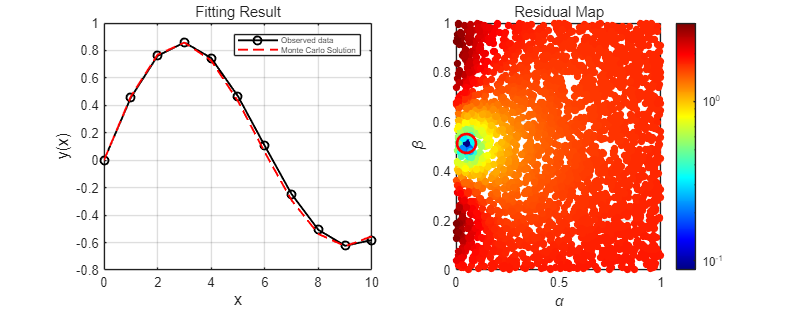

y_mc=f(ma(best_idx),mb(best_idx),x);

figure('Color','w','Position',[100,100,1800,700]);
subplot(1,2,1);
hold on; grid on; box on;
plot(x,y_obs,'k-o', 'LineWidth', 1.4);
plot(x,y_mc,'r--', 'LineWidth', 1.4);
xlabel('x','FontSize',12);
ylabel('y(x)','FontSize',12);
legend('Observed data','Monte Carlo Solution','fontsize',6);
title('Fitting Result');

subplot(1,2,2);
hold on; grid on; box on;
scatter(mp(1,:), mp(2,:), 30, r_mc, 'filled'); 
scatter(ma(best_idx),mb(best_idx),200,'MarkerEdgeColor','r','LineWidth',2);
colormap(jet);  
colorbar;  
set(gca,'ColorScale','log');
xlabel('\alpha');
ylabel('\beta');
title('Residual Map');

% exportgraphics(gcf,'MC_Results.png','Resolution',300);

## (b) Optimal Solution via Conjugate Gradient (CG) Method

The conjugate gradient (CG) method is a gradient-based iterative optimization algorithm for minimizing the residual error function.

Given an initial parameter pair $\((\alpha_0,\beta_0)\)$, the CG iteration proceeds as follows:

- Calculate the initial gradient $\({g}_0\) $and set the initial search direction: $\({p}_0 = -{g}_0\)$

- Perform line search to obtain the optimal step size $\(\alpha\)$, then update parameters: $\({x}_{k+1} = {x}_k + \alpha {p}_k\)$

- Compute the new gradient $\({g}_{k+1}\) $and update the conjugate coefficient (PR formula): $\(\beta_{k} = \frac{{g}_{k+1}^\top ({g}_{k+1} - {g}_{k})}{{g}_k^\top {g}_k}\)$

- Update the search direction for the next iteration: $\({p}_{k+1} = -{g}_{k+1} + \beta_k {p}_k\)$

Repeat the above steps until the residual error is smaller than the tolerance `tol`. The converged $(\alpha,\beta)$ is the optimal solution.

a0=0.25;b0=0.25;max_iter=1000;tol=1e-8;
[a_cg,b_cg]=CG(a0,b0,x,y_obs,max_iter,tol);
y_cg=f(a_cg,b_cg,x);
fprintf(['========== CG Optimal Results ==========\n' ...
    'Minimum Residual = %.6f\n' ...
    'Best alpha = %.6f\n' ...
    'Best beta = %.6f\n=====================================\n'], ...
    sqrt(sum((y_cg-y_obs).^2)), a_cg, b_cg);

========== CG Optimal Results ==========
Minimum Residual = 0.496156
Best alpha = 0.031350
Best beta = -5.836284


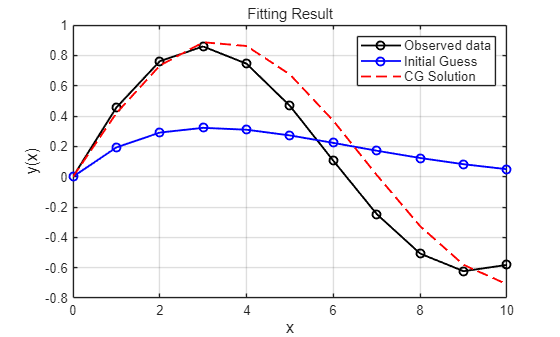

figure; hold on; grid on; box on;
hold on; grid on; box on;
plot(x,y_obs,'k-o', 'LineWidth', 1.4);
plot(x,f(a0,b0,x),'b-o','LineWidth',1.4)
plot(x,y_cg,'r--', 'LineWidth', 1.4);
xlabel('x','FontSize',12);
ylabel('y(x)','FontSize',12);
legend('Observed data','Initial Guess','CG Solution','fontsize',10);
title('Fitting Result');

## (c) Parameter Optimization Based on Grid Search Initialization

The convergence of the optimization process depends highly on good initial guesses.

 To verify global convergence, we generate $\mathrm{N}=20$ random initial points that are uniformly distributed within the model space $ \(\alpha, \beta \in [0, 2]\)$.

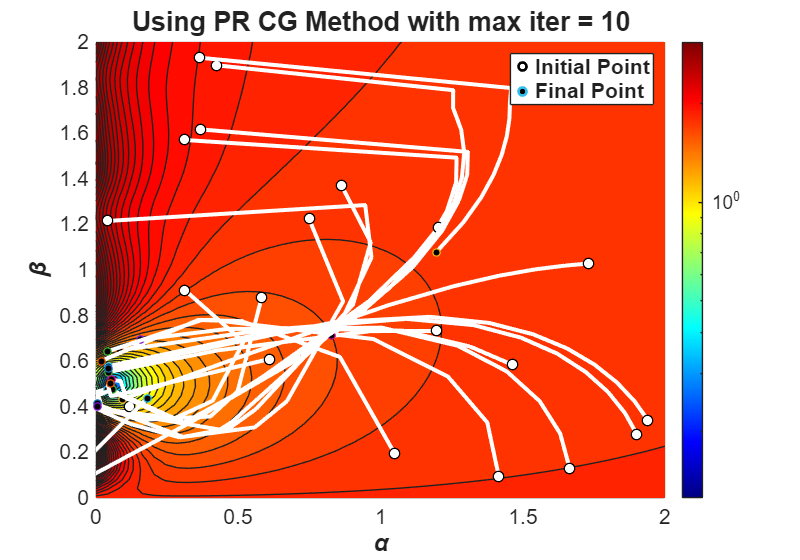

N=20;
rng(42);
a_initial=2*rand(1,N);
b_initial=2*rand(1,N);
figure('Color','w','Position',[100,100,1000,700]);
hold on; grid on; box on;
ag = linspace(0,2,50);
bg = linspace(0,2,50);
[AG, BG] = meshgrid(ag, bg);
EG = zeros(size(AG));
for i = 1:size(AG,1)
    for j = 1:size(AG,2)
        EG(i,j) = sqrt(sum((f(AG(i,j), BG(i,j), x)-y_obs).^2));
    end
end
contourf(AG, BG, EG, 40);
colormap(jet);
colorbar;
set(gca,'ColorScale','log')
r_min=100;
best_idx=100;
n=10;
for ii = 1:N
    [a_best,b_best,m_path,r]=CG(a_initial(ii),b_initial(ii),x,y_obs,10,1e-8);
    plot(m_path(1,:), m_path(2,:),'w-', 'LineWidth',3,'MarkerSize',4);
    scatter(m_path(1,1), m_path(2,1),60,'MarkerFaceColor','w','MarkerEdgeColor','k','LineWidth',1);
    scatter(m_path(1,end), m_path(2,end),30,'MarkerFaceColor','k','LineWidth',1);
    if r(end)<r_min
        r_min=r(end);
        best_idx=ii;
    end
end
set(gca,'FontSize',16); 
xlabel('\alpha','FontSize',18,'FontWeight','bold');
ylabel('\beta','FontSize',18,'FontWeight','bold');
title('Using PR CG Method with max iter = 10','FontSize',20,'FontWeight','bold');
h1 = scatter(nan,nan,80,'MarkerFaceColor','w','MarkerEdgeColor','k','LineWidth',2);
h2 = scatter(nan,nan,50,'MarkerFaceColor','k','LineWidth',2);
legend([h1,h2],'Initial Point','Final Point','Location','northeast','FontSize',16,'FontWeight','bold');
xlim([0 2]);
ylim([0 2]);

% exportgraphics(gcf,'CG_Path_Compare_2.png','Resolution',300);

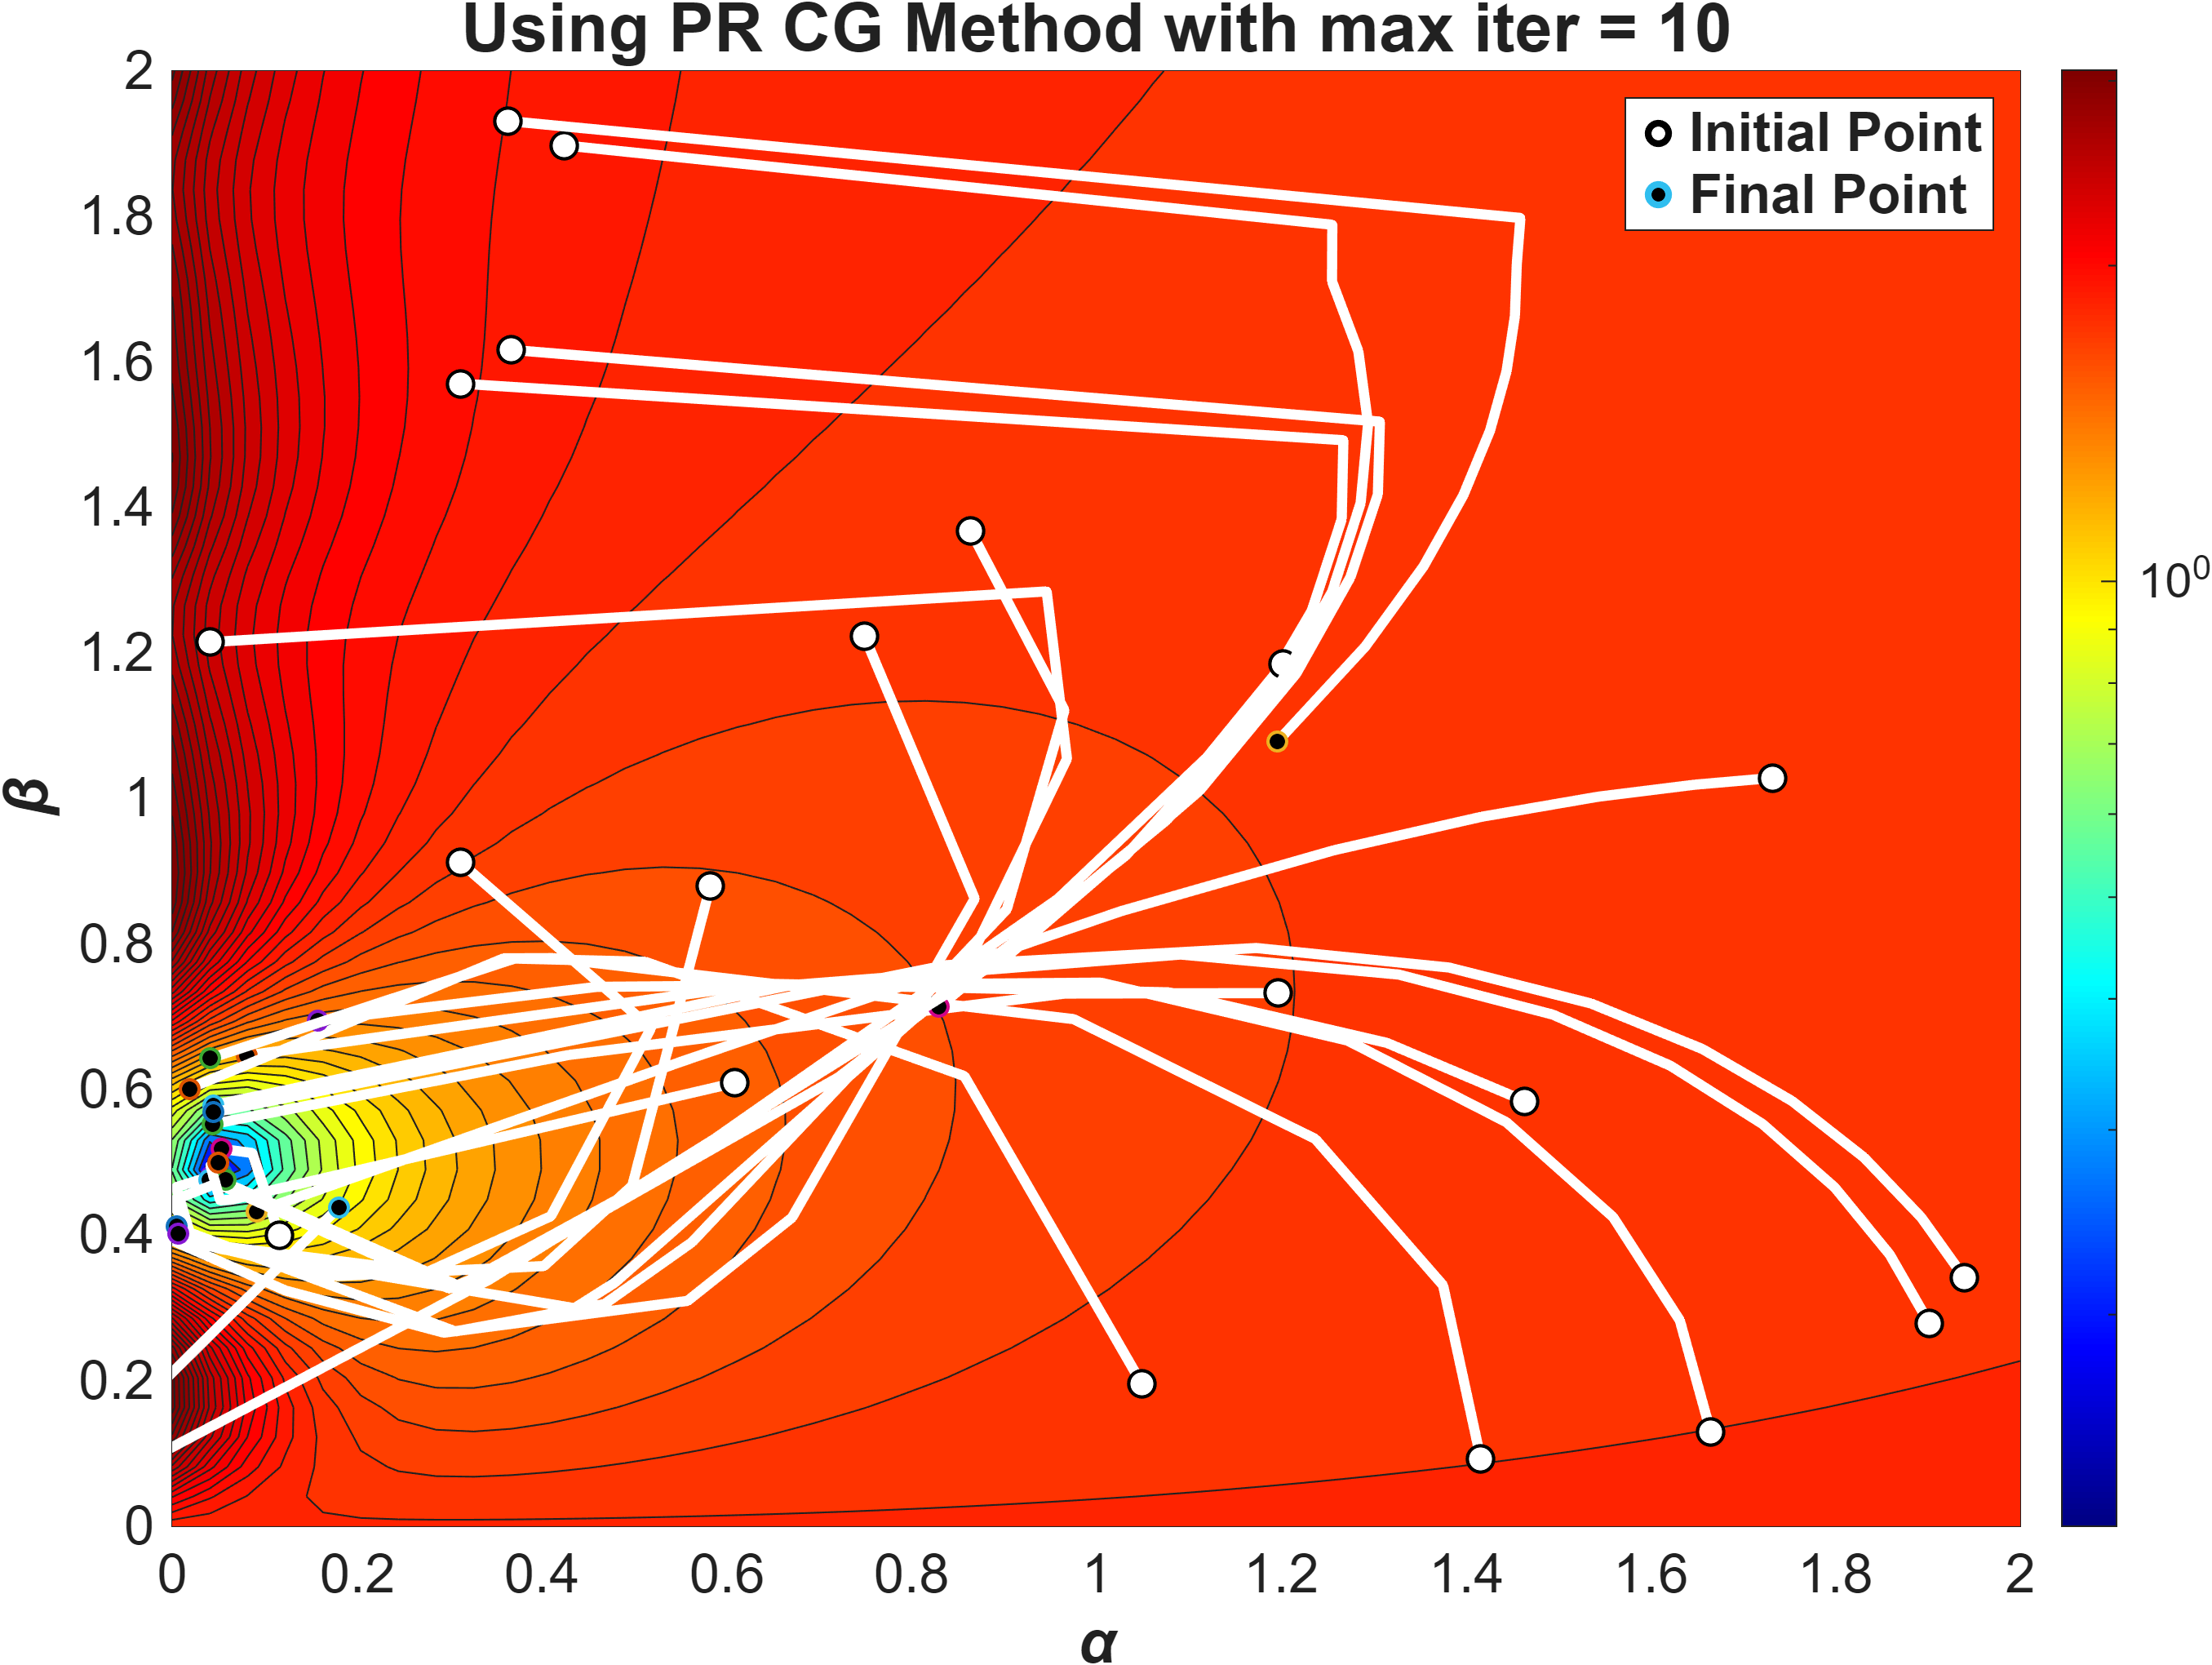

As we can see, almost all initial points update toward the minimal point. However, they cannot reach the true minimum due to the maximum iteration limit.

If we use a larger max iteration, we will see some paths pass by the minimal point.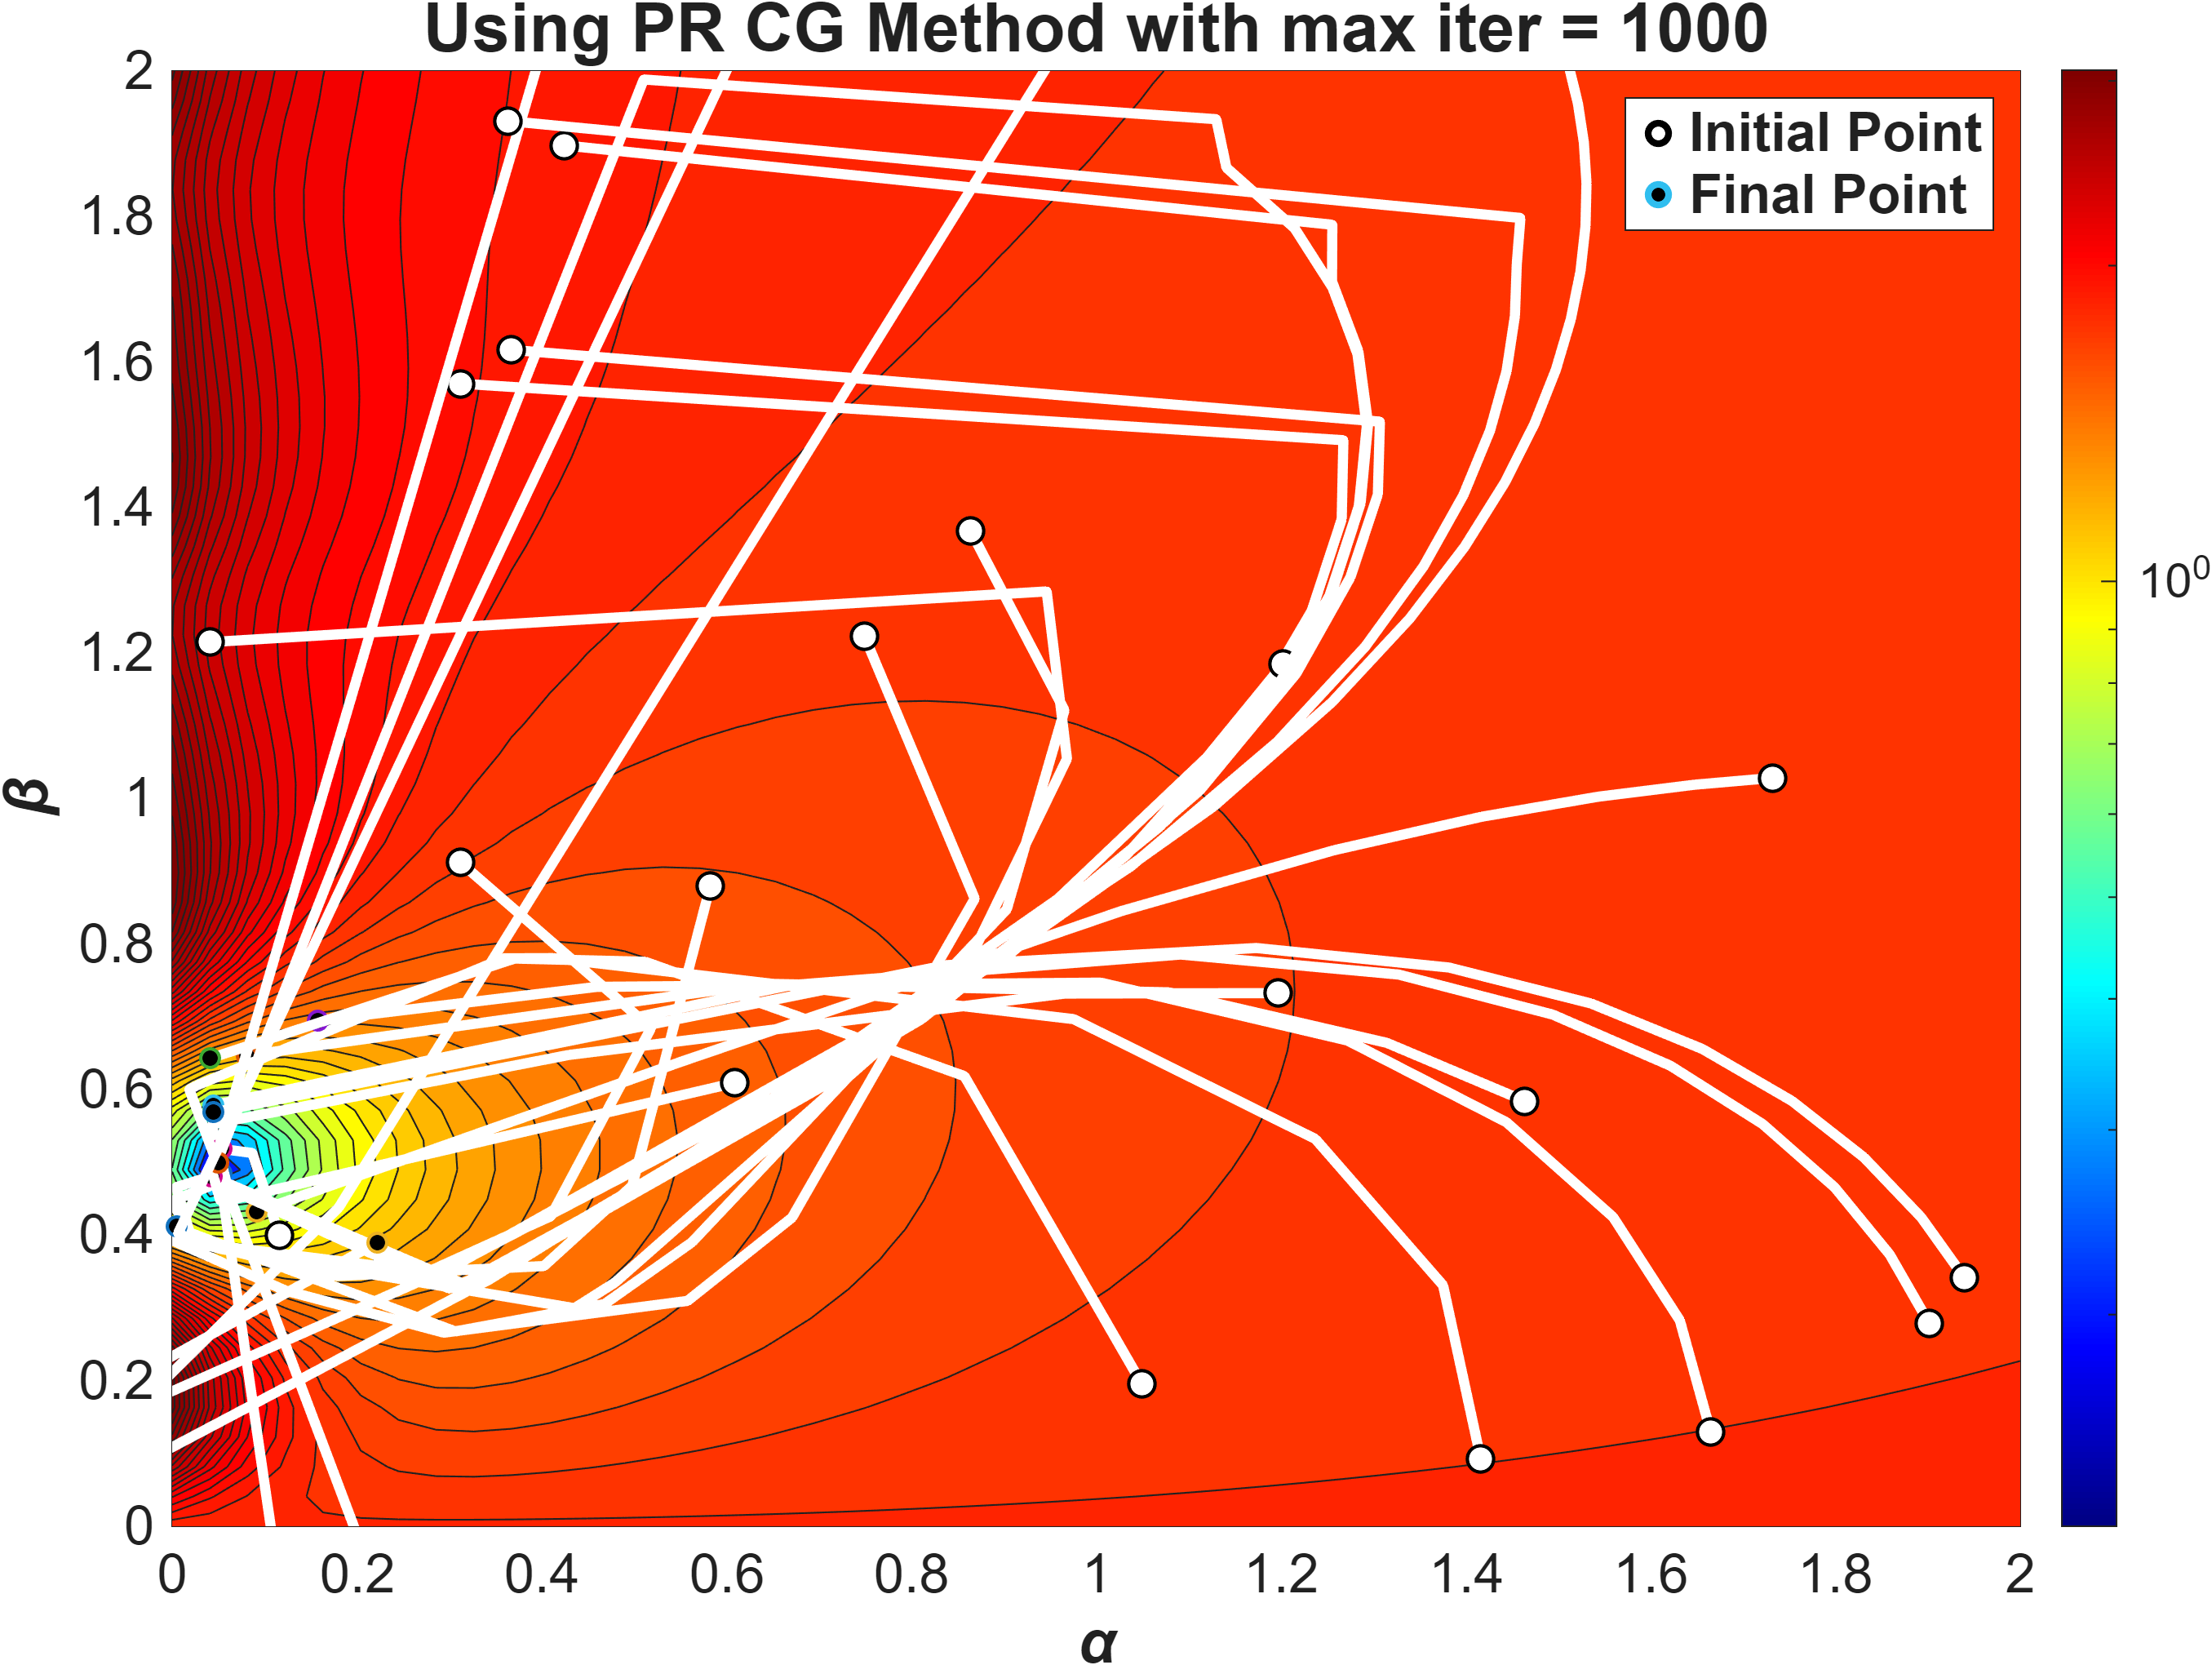

But if we start with a good initial guess, the path converges to the minimal point much faster.

Furthermore, if we use the original conjugate update formula,


$$\(\beta_k = \frac{{g}_{k+1}^\text{T}{g}_{k+1}}{{g}_{k}^\text{T}{g}_{k}}\)$$


the convergence becomes significantly less efficient.

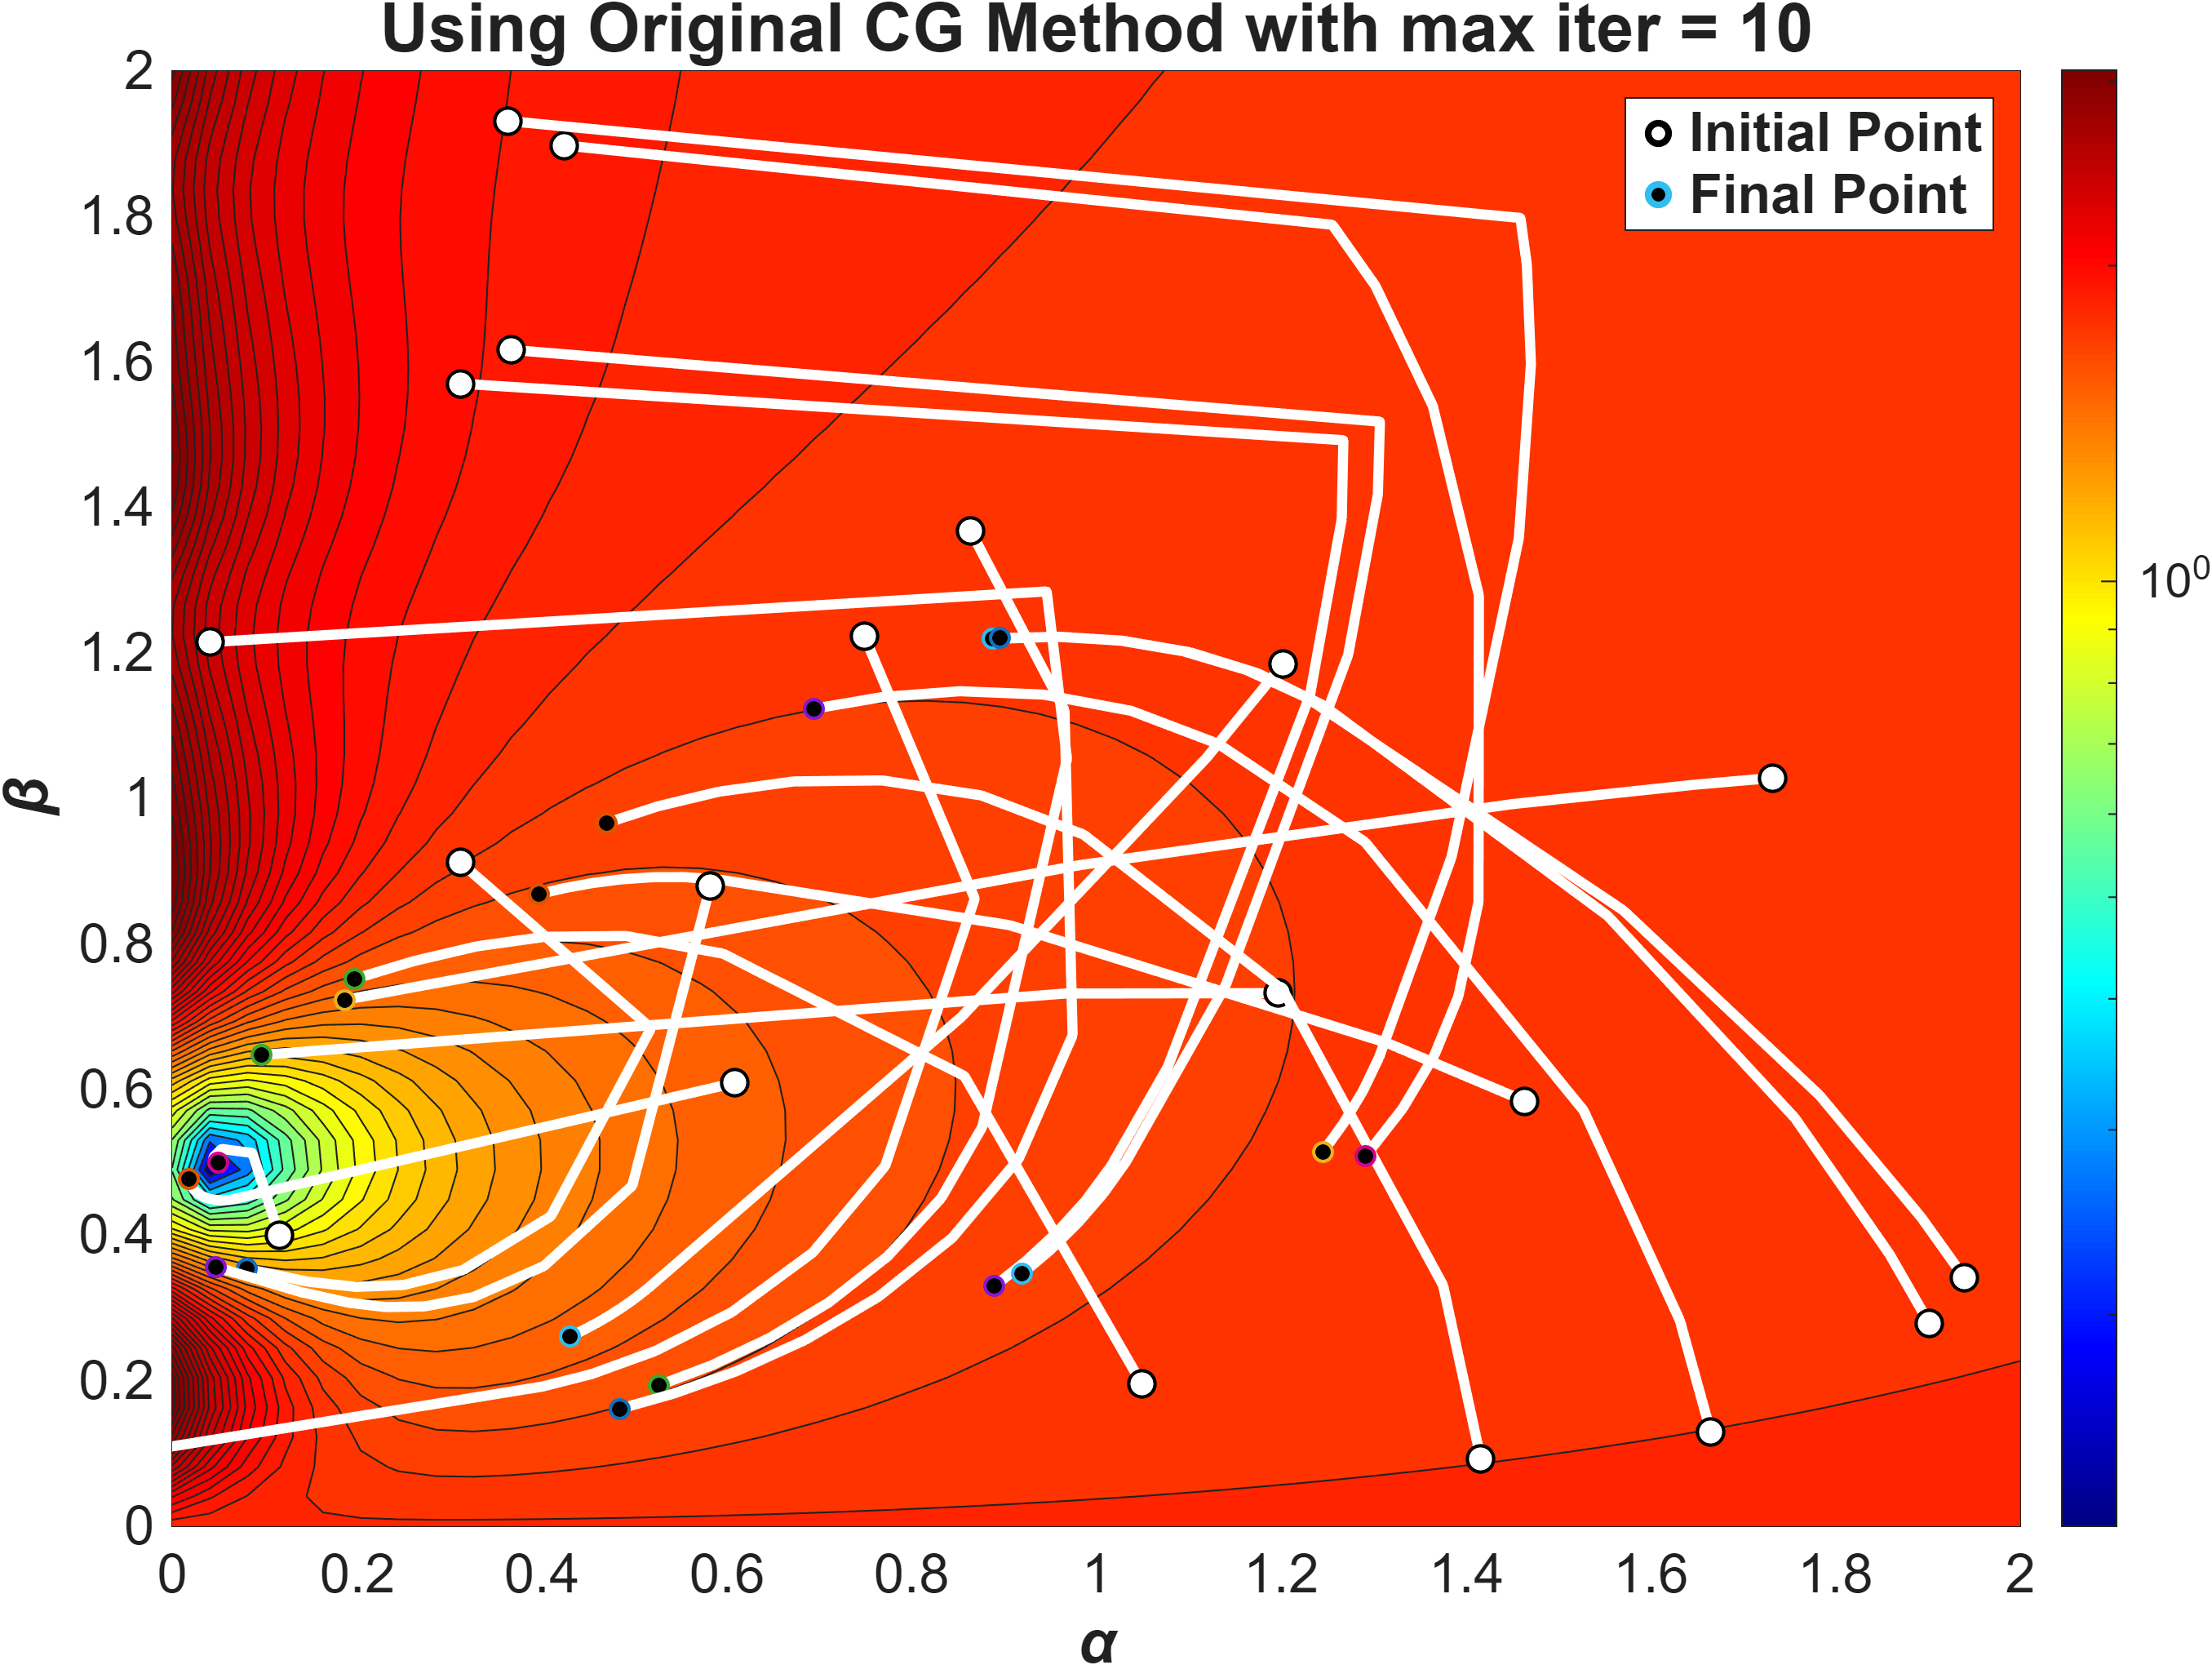

This is because the PR formula uses gradient difference information to reset the search direction more reliably, reduces unnecessary oscillations, and avoids backtracking away from the minimum, making the iteration more stable and robust for nonlinear least-squares problems.

a0=a_initial(best_idx);b0=b_initial(best_idx);
max_iter=10000;tol=1e-5;
[a_cg,b_cg,m_path]=CG(a0,b0,x,y_obs,max_iter,tol);
y_cg=f(a_cg,b_cg,x);
fprintf(['========== CG Optimal Results ==========\n' ...
    'Minimum Residual = %.6f\n' ...
    'Best alpha = %.6f\n' ...
    'Best beta = %.6f\n=====================================\n'], ...
    sqrt(sum((y_cg-y_obs).^2)), a_cg, b_cg);

========== CG Optimal Results ==========
Minimum Residual = 0.000084
Best alpha = 0.049999
Best beta = 0.500002


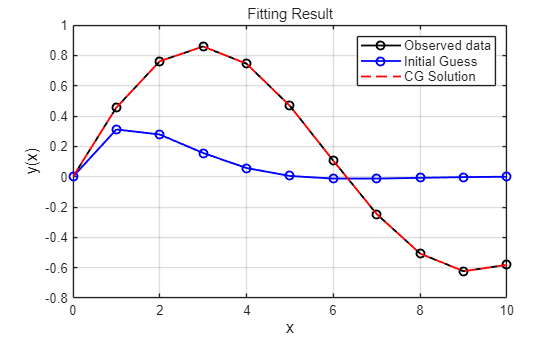

figure; hold on; grid on; box on;
hold on; grid on; box on;
plot(x,y_obs,'k-o', 'LineWidth', 1.4);
plot(x,f(a0,b0,x),'b-o','LineWidth',1.4)
plot(x,y_cg,'r--', 'LineWidth', 1.4);
xlabel('x','FontSize',12);
ylabel('y(x)','FontSize',12);
legend('Observed data','Initial Guess','CG Solution','fontsize',10);
title('Fitting Result');

## Appendix: Used Functions in This Sctipt

function y = f(a,b,x)
    y=exp(-a.*x).*sin(b.*x);
end

function [Ea,Eb] = dE(a,b,x,y_obs)
    f_val = f(a,b,x);
    res = f_val - y_obs;
    
    fa = -x .* exp(-a.*x) .* sin(b.*x);
    fb =  x .* exp(-a.*x) .* cos(b.*x);
    
    Ea = sum(res .* fa);
    Eb = sum(res .* fb);
end

function residual = res(mp,x,obs)
    residual=sqrt(sum((f(mp(1,:),mp(2,:),x)-obs).^2,1));
end

function s = linesearch(f, a, b)
    gr = (sqrt(5)-1)/2;
    c = b - gr*(b-a);
    d = a + gr*(b-a);
    for i = 1:30
        if f(c) < f(d)
            b = d;
        else
            a = c;
        end
        c = b - gr*(b-a);
        d = a + gr*(b-a);
    end
    s = (a + b)/2;
end

function [a_opt,b_opt,m,res] = CG(a0,b0,x,y_obs,max_iter,tol)
    m=zeros(2,max_iter);
    res=zeros(1,max_iter);
    m(1,1)=a0;
    m(2,1)=b0;
    [ga,gb]=dE(a0,b0,x,y_obs);
    g=[ga;gb];
    p=-g;
    res(1)=sqrt(sum((f(a0,b0,x)-y_obs).^2));
    iter_actual = 1;
    for ii = 1:max_iter-1
        f_val = @(s) sum((f(m(1,ii)+s*p(1), m(2,ii)+s*p(2), x) - y_obs).^2);
        alpha = linesearch(f_val, 0, 1);
        m(1,ii+1)=m(1,ii)+alpha*p(1);
        m(2,ii+1)=m(2,ii)+alpha*p(2);
        [ga_new,gb_new]=dE(m(1,ii+1),m(2,ii+1),x,y_obs);
        g_new=[ga_new;gb_new];
        % beta=g_new'*(g_new)/(g'*g);
        beta=g_new'*(g_new-g)/(g'*g);
        p=-g_new+beta*p;
        g=g_new;
        iter_actual = ii+1;
        res(ii+1)=sqrt(sum((f(m(1,ii+1),m(2,ii+1),x)-y_obs).^2));
        if abs(res(ii+1)-res(ii))<=tol
            break;
        end
    end
    m = m(:,1:iter_actual);
    res = res(1:iter_actual);
    [~,idx] = min(res);
    m = m(:,1:idx);
    a_opt = m(1,end);
    b_opt = m(2,end);
end